digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
'nndatasets','DigitDataset');

imds = imageDatastore(digitDatasetPath, ...
'IncludeSubfolders',true,'LabelSource','foldernames');

numTrainFiles = 750;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

tr_in = readall(imdsTrain);
tr_tg = imdsTrain.Labels;

ts_in = readall(imdsValidation);
ts_tg = imdsValidation.Labels;

omega_b = 0.2;
Nh = 784;
ts = 2;
f = @(bias, hidden_weights, hidden) tanh(bias + hidden_weights*hidden);
x0 = zeros(Nh,1);
phi = @eulerForward;
eps = 0.5;
eigs = -1:-1:-Nh;
ws = 7;
lambda_r = 0.1;
%Nl = 1;
seed = 1;

addpath src

net = NeuralODE(omega_b, Nh, ts, f, phi, eps, eigs, ws, lambda_r, seed);

net.hiddenState(tr_in);

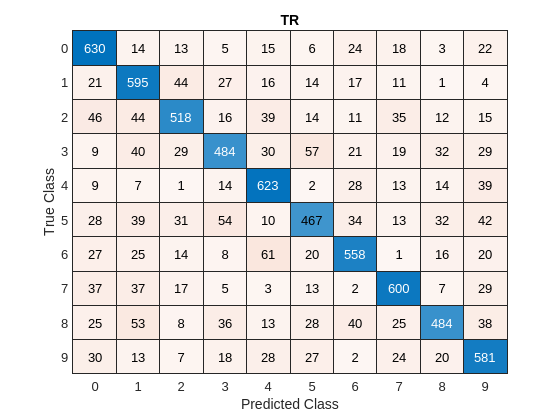

[net,pred_tr]=net.fit(tr_in,tr_tg);
figure
confusionchart(tr_tg, pred_tr);
title("TR")